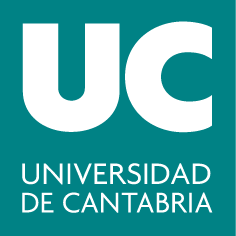

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 10: Ecuaciones diferenciales de segundo orden y sistemas de ecuaciones**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos		

- Representación gráfica de una muestra de curvas de la familia biparamétrica o solución general de una EDO lineal de segundo orden.	

- Resolver ecuaciones diferenciales de segundo orden y sistemas de ecuaciones diferenciales de primer orden de forma simbólica.

### Resumen teórico

#### Soluciones de EDOs de segundo orden

- **Solución general**: Una familia biparamétrica de funciones $y(x) = \phi(x,C_{1}, C_{2})$ es solución general de la ecuación diferencial de segundo orden si cada función de la familia satisface la ecuación y si dados unos valores $y_{0}$ e $y_{1}$, existen $C_{1}$ y $C_{2}$ tales que la correspondiente función cumpla que $y(x_{0})=y_{0}$ y que $y'(x_{0})= y_{1}$.

- **Solución particular**: Es cada una de las funciones que se obtiene de la solución general al dar valores a los parámetros.

- **Solución singular**: Es una solución que no puede extraerse de la solución general.

#### Problemas asociados a EDOs de segundo orden

- **Problema de valores iniciales**: Es el formado por la ecuación diferencial junto con los valores que debe de tomar la solución y su derivada en un mismo punto $x=x_{0}$:	$y(x_{0})=y_{0}$        $y'(x_{0})=y_{1}$

- **Problema de valores en la frontera: **Es el formado por la ecuación diferencial junto con los valores fijados para la solución en dos puntos distintos $x=x_{0}$ y $x=x_{1}$:           $y(x_{0})=y_{0}$        $y(x_{1})=y_{1}$

- **Problema mixto: **Es el formado por la ecuación diferencial junto con los valores fijados de la solución y su derivada en dos puntos distintos $x=x_{0}$ y $x=x_{1}$:    $\alpha_{1}y(x_{0})+\alpha_{2}y'(x_{0})=0$        $\beta_{1}y(x_{1})+\beta_{2}y'(x_{1})=0$ con  $\alpha_{i}, \beta_{i} \in \mathbb{R}$

#### Sistemas de ecuaciones diferenciales de primer orden


$$Ax'(t)+Bx(t)+Cy(t)=r_{1}(t)$$



$$Dy'(t)+Ex(t)+Fy(t)=r_{2}(t)$$


La solución buscada es $x(t), y(t)$.

### Comandos útiles

#### Comando para resolver ecuaciones diferenciales de forma exacta

- `syms y(x)`: crea la variable simbólica `y` que depende de `x`.

- `diff(var, n)`:  Para denotar la derivada de la variable simbólica `var` de orden `n`.

syms y(x)
Dy=diff(y,x,1) % Derivada primera
D2y=diff(y, x, 2)

- `dsolve('eq', 'cond')`: Para resolver ecuaciones diferenciales de forma simbólica. Si se incluye una lista de ecuaciones, resuelve un sistema de EDOs.

Ejemplos:

syms y(x)
solEDO=dsolve(diff(y,x) ==-3*x) 

Si se añade una condición inicial se obtiene la solución particular al problema de valor inicial:

solPVI=dsolve(diff(y,x) ==-3*x, y(0)==1) 

#### Otros comandos útiles para trabajar con funciones en formato simbólico

- `simplify(S)`: simplifica la expresión simbólica `S.`

- `fplot(FUN,[LIMS])`: dibuja la función `FUN `en el marco de la figura en que se añade o entre los límites indicados por `LIMS = [XMIN XMAX]`, si se especifican. Esta función sustituye a `ezplot`, cuyo uso no se aconseja. Ejemplo:

figure(1), fplot(@(x) x.^2.*sin(1./x),[-1,1])

###  Ejercicios resueltos

**1. Resolución simbólica**

Encontrar la solución a:

a) El problema de valor inicial: $y''-10y' +25y=0$        $y(0)=3$        $y'(0)=13$

b) El sistema de ecuaciones: $x'(t)=3y, y'(t)=2x-y$

c) El sistema de ecuaciones: $x'(t)=(7x+4y)/3$     $x(0)=3$    $y'(t)=(2x+5y)/3$    $y(0)=0$

a) El problema de valor inicial: $y''-10y' +25y=0$        $y(0)=3$        $y'(0)=13$

syms y(x)
Dy=diff(y,x,1);
D2y=diff(y,x,2);
yexacta=dsolve(D2y -10*Dy+25*y==0,y(0)==3, Dy(0)==13) 

b) El sistema de ecuaciones: $x'(t)=3y, y'(t)=2x-y$

syms y(t) x(t)
Dy=diff(y,t,1);
Dx=diff(x,t,1);
[x, y]=dsolve(Dx==3*y,Dy==2*x-y) 

c) El sistema de ecuaciones: $x'(t)=(7x+4y)/3$     $x(0)=3$    $y'(t)=(2x+5y)/3$    $y(0)=0$

syms y(t) x(t)
Dy=diff(y,t,1);
Dx=diff(x,t,1);
[x, y]=dsolve(Dx==(7*x+4*y)/3,Dy==(2*x+5*y)/3, x(0)==3, y(0)==0) 

**2. Representación de la solución particular de un problema de valor inicial y un problema de valores en la frontera**

Partimos de la familia de curvas $y(x)=C_{1}e^{x}+C_{2}e^{-x}$ que es la solución general de $y''=y$.

a) Representa con Matlab en la ventana $[-2,2]\times[-8,10]$ una muestra de soluciones de $y''=y$, primero fijando un punto de paso $P(0,2)$ y dejando variar la pendiente los valores $y'(0)=[-4:2:4]$ y, en segundo lugar, fijando la pendiente a $y'(0)=2$ y variando el punto de paso con $y(0)=[-4:2:4]$. Destaca en color rojo en la misma figura la solución particular del problema de valor inicial: $y''=y$        $y(0)=2$        $y'(0)=2$

b) Representa con Matlab en la ventana $[0,2]\times[-4,4]$ una muestra de soluciones de $y''=y$, primero fijando un punto de paso $P(0,2)$ y dejando variar la ordenada de otro punto $Q(2, y_1)$, con $y_{1}=[-4:2:4]$ y, en segundo lugar, fijando  el punto $Q(2,2)$ y dejand variar la ordenada del punto $P(0, y_0)$ con $y_{0}=[-4:2:4]$. Destaca en color rojo en la misma figura la solución particular del problema de valor inicial: $y''=y$        $y(0)=2$        $y(2)=2$

a) Representa con Matlab en la ventana $[-2,2]\times[-8,10]$ una muestra de soluciones de $y''=y$, primero fijando un punto de paso $P(0,2)$ y dejando variar la pendiente los valores $y'(0)=[-4:2:4]$ y, en segundo lugar, fijando la pendiente a $y'(0)=2$ y variando el punto de paso con $y(0)=[-4:2:4]$. Destaca en color rojo en la misma figura la solución particular del problema de valor inicial: $y''=y$        $y(0)=2$        $y'(0)=2$

En primer lugar, escribimos los coeficientes $C_{1}$ y $C_{2}$ en función de $y(0), y'(0)$ que son los datos que tenemos con las condiciones iniciales en $x_{0}=0$:


$$y=C_{1}e^{x}+C_{2}e^{-x} \Rightarrow y(0)=C_{1}+C_{2}$$



$$y'=C_{1}e^{x}-C_{2}e^{-x} \Rightarrow y'(0)=C_{1}-C_{2}$$


Despejamos $C_{1}, C_{2}$: 


$$C_{1}=\frac{y(0)+y'(0)}{2}$$
        
$$C_{2}=\frac{y(0)-y'(0)}{2}$$


Fijando el valor $y(0)=2$: 


$$C_{1}=\frac{2+y'(0)}{2}=1+\frac{y'(0)}{2}$$
        
$$C_{2}=\frac{2-y'(0)}{2}=1-\frac{y'(0)}{2}$$


x=-2:.02:2;
figure(1)
grid on; hold on
for dy0=-4:2:4
    y=(1+dy0/2)*exp(x)+(1-dy0/2)*exp(-x);
    plot(x,y,'b')
    axis([-2 2 -8 10])% ajusta la ventana
end
title('cinco curvas de la familia cumpliendo y(0)=2')

Fijando el valor $y'(0)=2$: 


$$C_{1}=\frac{y(0)+2}{2}=1+\frac{y(0)}{2}$$
        
$$C_{2}=\frac{y(0)-2}{2}=-1+\frac{y(0)}{2}$$


for y0=-4:2:4
    y=(1+y0/2)*exp(x)+(-1+y0/2)*exp(-x); 
    plot(x,y,'g')
    axis([-2 2 -8 10])
end
title('5 curvas de la familia cumpliendo y(0)=2 y 5 cumpliendo dy/dx(0)=2')

La solución al problema de valor inicial verifica: $C_{1}=\frac{2+2}{2}=2$        $C_{2}=\frac{2-2}{2}=0$

Luego la solución particular es $y(x)=2e^{x}$, como se obtiene también con Matlab:

syms y(x)
Dy=diff(y,x,1);
D2y=diff(y,x,2);
yexacta=dsolve(D2y ==y,y(0)==2, Dy(0)==2) % Solución al pvi
% Dibuja la curva yexacta obtenida simbólicamente
h1=fplot(yexacta);
% Asigna el color rojo a la curva dibujada con fplot
set(h1,'Color','r')  
title('en rojo la unica que cumple y(0)=2 y dy/dx(0)=2')
hold off

b) Representa con Matlab en la ventana $[0,2]\times[-4,4]$ una muestra de soluciones de $y''=y$, primero fijando un punto de paso $P(0,2)$ y dejando variar la ordenada de otro punto $Q(2, y_1)$, con $y_{1}=[-4:2:4]$ y, en segundo lugar, fijando  el punto $Q(2,2)$ y dejand variar la ordenada del punto $P(0, y_0)$ con $y_{0}=[-4:2:4]$. Destaca en color rojo en la misma figura la solución particular del problema de valor inicial: $y''=y$        $y(0)=2$        $y(2)=2$

En primer lugar, escribimos los coeficientes $C_{1}$ y $C_{2}$ en función de $y(0), y(2)$ que son los datos que tenemos.

Partiendo de la solución general:$y=C_{1}e^{x}+C_{2}e^{-x}$


$$y(0)=C_{1}+C_{2}$$
        
$$y(2)=C_{1}e^2+C_{2}e^{-2}$$


Multiplicando la primera por $e^{-2}$ y restando ambas:


$$y(0)e^{-2}=C_{1}e^{-2}+C_{2}e^{-2}$$
       
$$y(2)=C_{1}e^2+C_{2}e^{-2}$$
        
$$\Rightarrow C_{1}=\frac{y(2)-y(0)e^{-2}}{e^{2}-e^{-2}}$$


Multiplicando la primera por $e^{2}$ y restando ambas:


$$y(0)e^{2}=C_{1}e^{2}+C_{2}e^{2}$$
       
$$y(2)=C_{1}e^2+C_{2}e^{-2}$$
        
$$\Rightarrow C_{2}=\frac{y(0)e^{2}-y(2)}{e^{2}-e^{-2}}$$


Fijando el valor $y(0)=2$: 


$$C_{1}=\frac{y(2)-2e^{-2}}{e^{2}-e^{-2}}$$
        
$$C_{2}=\frac{2e^{2}-y(2)}{e^{2}-e^{-2}}$$


x=0:.01:2;
figure(3)
grid on
hold on
for y1=-4:2:4
    y=((y1-2*exp(-2))*exp(x)+(2*exp(2)-y1)*exp(-x))/(exp(2)-exp(-2));
    plot(x,y,'b')
    axis([0 2 -4 4])
end
title('cinco curvas de la familia cumpliendo y(0)=2')

Fijando el valor $y(2)=2$: 


$$C_{1}=\frac{2-y(0)e^{-2}}{e^{2}-e^{-2}}$$
        
$$C_{2}=\frac{y(0)e^{2}-2}{e^{2}-e^{-2}}$$


for y0=-4:2:4
    y=((2-y0*exp(-2))*exp(x)+(y0*exp(2)-2)*exp(-x))/(exp(2)-exp(-2));
    plot(x,y,'g')
    axis([0 2 -4 4])
end
title('cinco curvas de la familia cumpliendo y(0)=2 y cinco cumpliendo y(2)=2')

La solución al problema de valor en la frontera verifica: $C_{1}=\frac{2-2e^{-2}}{e^{2}-e^{-2}}$        $C_{2}=\frac{2e^{2}-2}{e^{2}-e^{-2}}$

Luego la solución particular es $y(x)=\frac{2-2e^{-2}}{e^{2}-e^{-2}}e^{x}+\frac{2e^{2}-2}{e^{2}-e^{-2}} e^{-x}$, como se obtiene también con Matlab:

syms y(x)
Dy=diff(y,x,1);
D2y=diff(y,x,2);
yexacta=dsolve(D2y ==y,y(0)==2, y(2)==2) % Solución al pvf
h1=fplot(yexacta);
set(h1,'Color','r')
title('en rojo la única que cumple y(0)=2 y y(2)=2')
hold off